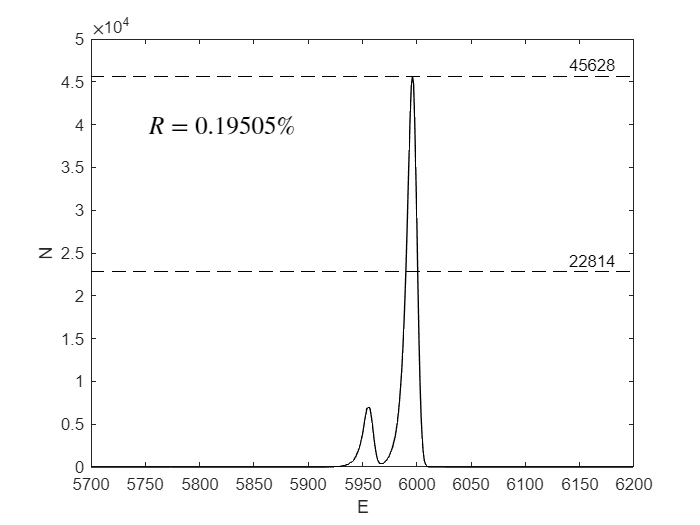

clear
M = readmatrix("能谱数据20221110_Am_0.csv");
ra = [5700 6200];
N = M(5700:6200,1);
ch = M(5700:6200,2);
[~,ind1] = max(ch);
mm = ch(ind1);
m2 = ch(ind1)/2;
hold on
plot(N,ch,'k-')
%grid on
plot(ra,[mm mm],'k --')
plot(ra,[m2 m2],'k --')
x=5700:50:6200;
set(gca,'xtick',x);  %设置x轴刻度（和数据有关）
xlim(ra)
% ch1 = ch(1:ind1);
% ch2 = ch(ind1 + 1:end);
% [~,ind2] = min(abs(ch1 - m2));
% [~,ind3] = min(abs(ch2 - m2));
% le = length(ch1) - ind2 + ind3;
% FWHM = le/length(ch)*(ra(2) - ra(1));
% E0 = ind1/length(ch)*(ra(2) - ra(1)) + ra(1);
FWHM = 10.6948;
E0 = 5483.17;
R = FWHM/E0*100;
te = ['$R = ',num2str(R),'\%$'];
%text(5750,40000,'$R = \frac{FWHM}{E_0}$','Interpreter','latex','FontSize',15)
text(5750,40000,te,'Interpreter','latex','FontSize',15)
text(6140,mm + 1300,num2str(mm))
text(6140,m2 + 1300,num2str(m2))
box on
ylabel('N')
xlabel('E')